# Average channel gain with interference

Here, we need to know if the channel gain an its mean is dependent on the RIS elements tuned for the other basestation.


$$$
R_{k,m} = log_2(1+\frac{ |h_{k,m}|^2 \alpha_{k,m}P_T }
	{|h_{k,m}|^2\sum_{j=k+1}^{N_m}\alpha_{j,m} + \sigma^2})
\\
	h_{k,1} = \sum_{i=1}^{N}a_{i1}h^r_{i,k}e^{j\theta_{i,1}}g_i + \sum_{i=1}^{N}a_{i2}h^r_{i,k}e^{j\theta_{i,2}}g_i + h^d_{k,1}$$$


This is what we cal interference here:


$$I=\sum_{i=1}^{N}a_{i2}h^r_{i,k}e^{j\theta_{i,2}}g_i $$


We can see from the results that the channel gain of users will increase on average when there are a couple of RIS elements on and configured randomly.

We have also investigated the effect of these elements on achievable rate of $BS_1$users.

%% Before we start
clc
close all
addpath('C:\Users\Asus irG\OneDrive\Documents\MATLAB\Thesis numerical analysis\RIS-Sharing-Scenario-main\common methods') % You need to change the address in case you run it on your computer

%% parameters
N1 = 3 ;                                 % No. first Basestations users
N2 = 3 ;                                 % No. first Basestations users
R1 = 10 ;                                % BS1 user area center radius
R2 = 10 ;                                % BS2 user area center radius    
N_i = 24 ;                                % No.  IRS elements
q_t = 1/8 ;                              % Quantization step-size
N_iter = 2 ;
SV = 3 ;                                  % Scenario Variable
P_T = (10^(40/10)) * 1e-3 ;                 % BS power
% [x0 , y0 , z0] = deal(50 , 20 , 0) ;              % user area center
[x1 , y1 , z1] = deal(0 , 0 , 0) ;                % BS1 location
[x2 , y2 , z2] = deal(100 , 10 , 0) ;             % BS2 location
[x_i , y_i , z_i] = deal(50 , 30 , 10) ;          % IRS location
M_t = 1 ;                                 % No. of transmitter antennas
M_r = 1 ;                                 % No. of receiver antennas
d_IB = 100 ; 
alpha_d = 3.76 ; 
alpha_r = 2 ; 
BW = 10e7 ; 
noise_power = (10^(-114/10)) ;            % -169dbm/Hz
r = 0.1 ; 
r = 0.3 ; 
interference = 1 ;                      % Interference existence between two
                                        % BSs(1 means we consider it).
epsilon = 0.05 ;

Lets say 2 tiles are allocated to BS1 and $$N_{i1}$$ is allocated to BS2.

N_i1 = floor((3-1) * N_i * q_t) ;     % No. of elements allocated to BS1
% N_i2 = floor((4-1) * N_i * q_t) ;     % No. of elements allocated to BS2
%% users location
x = zeros(N1+N2 , 1) ; 
y = zeros(N1+N2 , 1) ; 
z = 1.5 * ones(N1+N2 , 1) ; 
x(1 : N1 , 1) = 35 ; 
x(N1+1 : N2+N1) = 55 ; 
y(1 : N1 , 1) = 25 ; 
y(N1+1 : N2+N1) = 10 ; 
%% Calculating Rates
rate = zeros(ceil(1/q_t)+1 , ceil(1/q_t)+1 , 2 , SV) ; 
var = [] ; 
save('EPG_utility.mat' , 'var')
save('rate.mat' , 'var')
save('loopcounter.mat' , 'var') 
start = 1 ;   
step = 1 ;     
m = repmat('.' ,  1 ,  1 + floor((y_i-start)/step)) ; 
channel_gain11 = zeros( N1,SV) ;
channel_gain12 = zeros( N1,SV) ;
I = zeros( SV , 1) ; % Maximum interference
tic
rate1 = zeros(SV,1) ;
rate2 = zeros(SV,1) ;
x0 = x ;
y0 = y ;
t = 2 * pi * rand(N1,1) ;
R = [R1 ; R2] ;
radius  =  R(1) * sqrt(rand(N1,1)) ;
x(1 : N1) = x0(1 : N1)  +  radius.* cos(t) ;
y(1 : N1) = y0(1 : N1)  +  radius.* sin(t)  ;
for N_i2 = floor(N_i*q_t*(start : step : (SV - 1) * step + start))
    m(floor((N_i2 - start)/ step) + 1) = '|' ;
    disp(m)
    i = 1+floor((N_i2/(N_i*q_t)-start)/step) ;
    for j = 1 : N_iter
        if M_t==1
            [h_d1, G1, h_r1] = ChannelGain(M_t, M_r, N1, N_i, x(1 : N1), y(1 : N1), z(1 : N1), x1, y1,...
                                    z1, x_i, y_i, z_i, alpha_d, alpha_r) ;
            [h_d2, G2, h_r2] = ChannelGain(M_t, M_r, N2, N_i, x(N1+1 : N1+N2), y(N1+1 : N1+N2), z(N1+1 : N1+N2), x2, y2,...
                                    z2, x_i, y_i, z_i, alpha_d, alpha_r) ;
            [~, Z_cvx1] = Rate2(h_d1, G1(1 : N_i1), h_r1(1 : N_i1, : ), N1, N_i1, P_T, noise_power, N_iter) ;
            [~, Z_cvx2] = Rate2(h_d2, G2(1 : N_i2), h_r2(1 : N_i2, : ), N2, N_i2, P_T, noise_power, N_iter) ;
%             Z_cvx2 = exp((2 * 1j * pi * rand(N_i2, 1))) ;

            interference = 0 ;
            Theta = diag([Z_cvx1 ; interference * Z_cvx2 ;zeros(N_i-N_i1-N_i2,1)]) ;
            channel_gain11( 1 : N1 , i) = channel_gain11(1 : N1 , i) + abs(h_d1 + h_r1' * Theta * G1);  % With interference
            [exact_rate1, b_star1] = SISONoma(epsilon, sort(abs(h_d1 + h_r1' * Theta * G1)).^2 * P_T / noise_power) ;
            rate1(i) = rate1(i) + exact_rate1 ;

            interference = 1 ;
            Theta = diag([Z_cvx1 ; interference * Z_cvx2 ;zeros(N_i-N_i1-N_i2,1)]) ;
            channel_gain12(1 : N1 , i) = channel_gain12(1 : N1 , i) + abs(h_d1 + h_r1' * Theta * G1) ; % No interference         
            [exact_rate2, b_star2] = SISONoma(epsilon, sort(abs(h_d1 + h_r1' * Theta * G1)).^2 * P_T / noise_power) ;
            rate2(i) = rate2(i) + exact_rate2 ;
        end
    end 
end

..|...........................
..|..|........................
..|..|..|.....................


toc

Elapsed time is 36.952651 seconds.


channel_gain11 = 1 * channel_gain11/N_iter ;
channel_gain12 = 1 * channel_gain12/N_iter ;
for N_i2 = floor(N_i*q_t*(start : step : (SV - 1) * step + start))
    i = 1+floor((N_i2/(N_i*q_t)-start)/step) ; 
    I(i, 1) = max(abs((channel_gain12(1 : N1 , i) - channel_gain11(1 : N1 , i) )./...
        channel_gain12(1 : N1 , i) )) ; 
end

Here we plot interference effect on the channel gain and achievable rate.

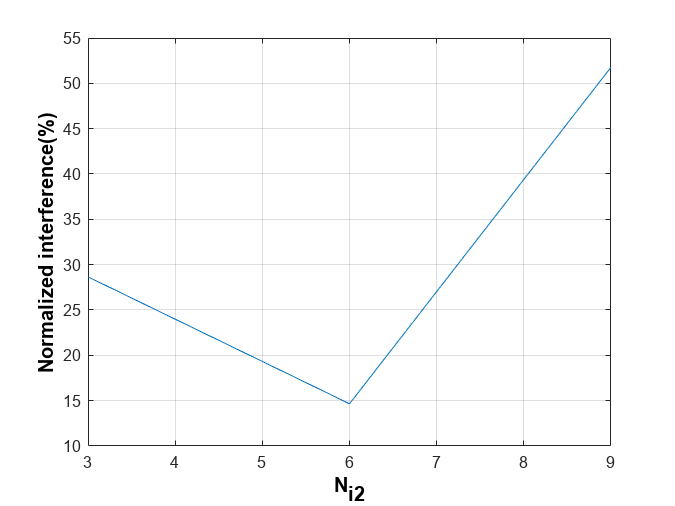

figure
plot(floor(N_i*q_t*(start : step : (SV - 1) * step + start)),100 * I)
xlabel('N_{i2}','FontSize',12,...
       'FontWeight','bold','Color','black')
ylabel('Normalized interference(%)','FontSize',12,...
       'FontWeight','bold','Color','black')
set(gcf,'color','w');
grid on
saveas(gcf,['Normalized interference for ', num2str(N_iter),' Iterations and at most ', num2str(N1),' users.epsc'])

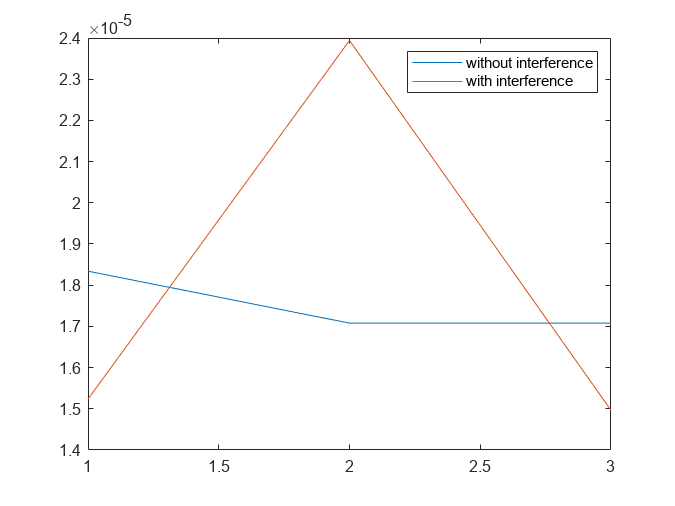


figure
plot(channel_gain11(:,1)')
hold on
plot(channel_gain12(:,1)')
legend('without interference','with interference')

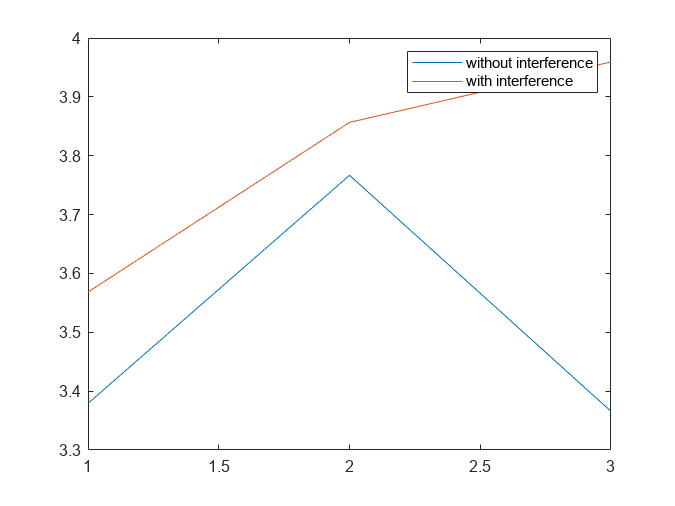


figure
plot(rate1)
hold on
plot(rate2)
legend('without interference','with interference')

We need to know this average


$$	\mathbb{E}(h_{r1}^H\Theta_1 g_{1}
	g_2^H\Theta_2^H h_{r2})$$


or


$$\mathbb{E}(Y_1 =X_1X_2X_3), \quad X_i \sim Rayleigh(\alpha_i)\\
\mathbb{E}(Y_2 =|X_1X_2X_3|^2), \quad X_i \sim Rayleigh(\alpha_i)\\
\mathbb{E}(Y_3 =X_1X_2X_3\theta), \quad X_i \sim Rayleigh(\alpha_i), \quad \theta \sim U(0,2\pi)$$


where all the channel gains have a Rayleigh distribution.

N1 = 1 ;                                 % No. first Basestations users
N_i = 1 ;
N_iter = 10000000 ;
x = zeros(N1+N2 , 1) ; 
y = zeros(N1+N2 , 1) ; 
z = 1.5 * ones(N1+N2 , 1) ; 
x(1 : N1 , 1) = 35 ; 
x(N1+1 : N2+N1) = 55 ; 
y(1 : N1 , 1) = 25 ; 
y(N1+1 : N2+N1) = 10 ; 
alpha_d = 0 ;
alpha_r = 0 ;
Y1 = 0 ;
Y2 = 0 ;
Y3 = 0 ;
    [h_d1, G1, h_r1] = ChannelGain(M_t, M_r, N1, N_i, x(1 : N1), y(1 : N1), z(1 : N1), x1, y1,...
                                    z1, x_i, y_i, z_i, alpha_d, alpha_r) ;
for k = 1 : N_iter
    Z_cvx = exp((2 * 1j * pi * rand(N_i, 1))) ;
    Y1 = Y1 + h_d1 * G1 * h_r1 * (1)' ;
    Y2 = Y2+ abs(h_d1 * G1 * h_r1)^2 ;
    Y3 = Y3 + h_d1 * G1 * h_r1 * (Z_cvx)' ;
end
Y1/N_iter
Y2/N_iter
Y3/N_iter